# System Identification

## Lab Exercises

The Simulink model shown below applies a sinusoid voltage input to the Qube Servo. This input command is a sum of four individual sinusoids of varying amplitude and frequency.  

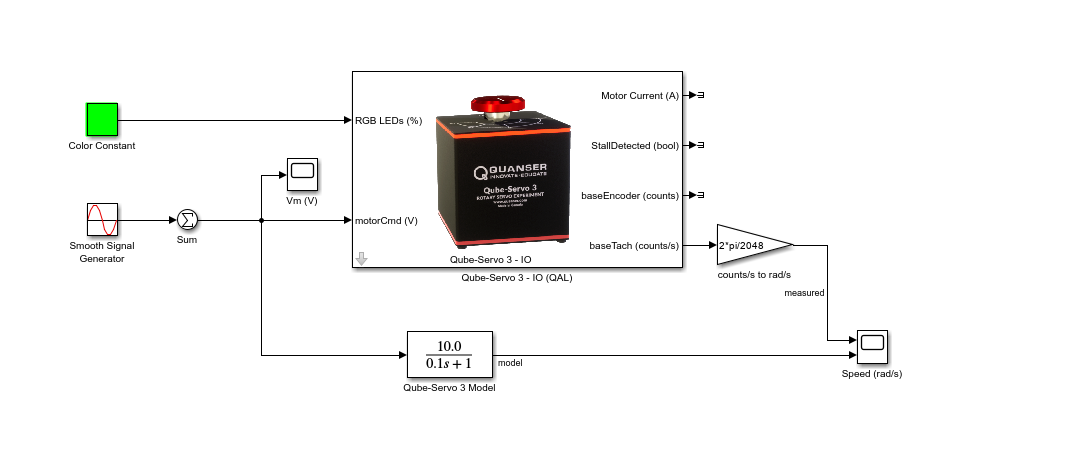

Set the *Simulation stop time* of the Simulink model to apply the step input for a certain duration, e.g. 10 s. Using the saved response, the model parameters can then be found as discussed in Background section of this lab. 

### Lab 1: Collecting Data

Follow these steps to find the model of the Qube-Servo 3 experimentally using the step response method:

**Step 1:** Run Quanser Interactive Labs (QLabs) software and open *Qube 3 - DC Motor* | *Servo Workspace*. If you have any issues running the software, please go to the [QLabs support page](https://portal.quanser.com/Support).

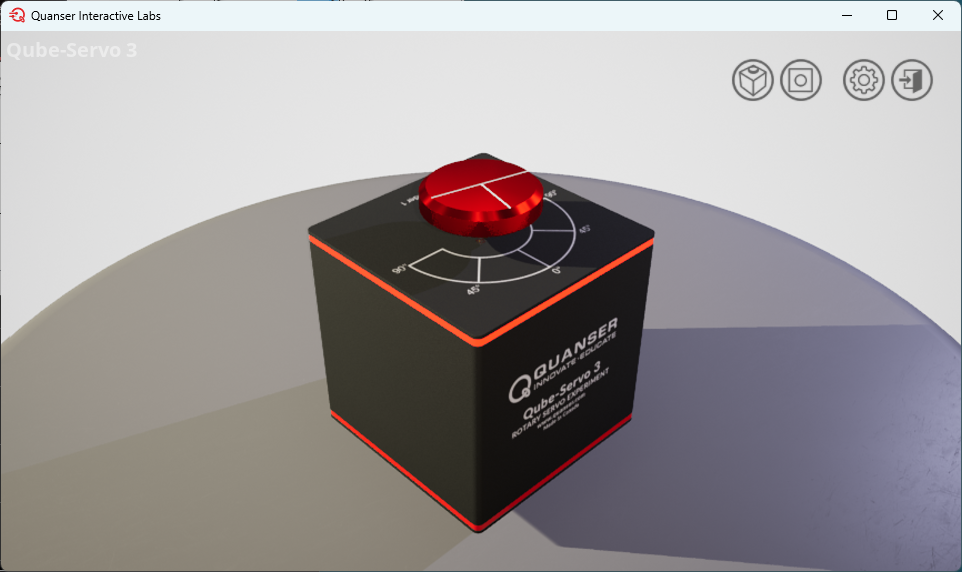

**Step 2:** Open the *q_qube3_step_response *Simulink model shown above.

 q_qube3_system_identification; % opens the Simulink mode shown above (if supplied)

**Step 3:** Run the model to apply a sinusoid command to the virtual servo. The scope response should be similar as shown below. The yellow signal in the *Speed *scope is the measured speed from the virtual servo and the blue signal is the speed from the transfer function model.  

  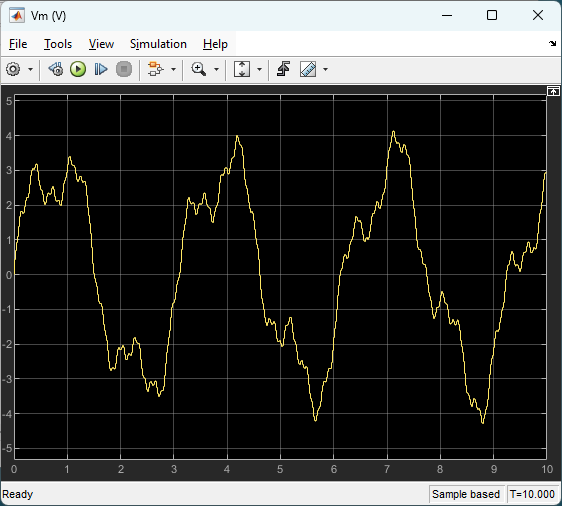 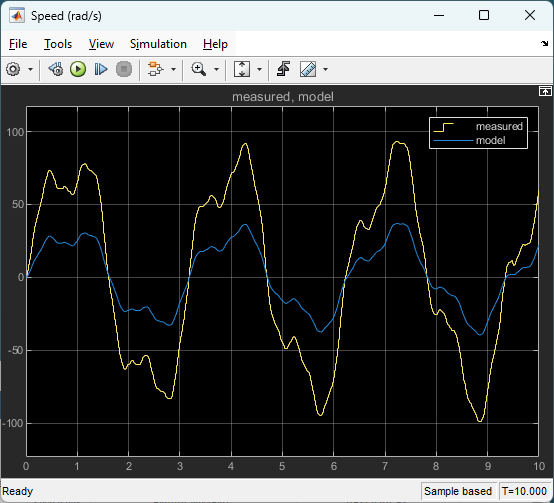

**Assessment 1: **Plot the response in MATLAB figure. The scopes are configured to save the measured load/disk speed and motor voltage to the MATLAB workspace in the variables `data_wm` and `data_Vm`. The `data_wm.time` is the time vector, `data_wm.signals(1).values` is the measured speed, `data_Vm.time` is the time vector, and `data_Vm.signals` is the applied voltage.

**    Solution: **If the measured data is saved to the variables `data_wm` and `data_Vm`, the following command lines will generate the figure below.

subplot(2,1,1);
plot(data_wm.time,data_wm.signals(1).values);
ylabel('\omega_m (rad/s)');
subplot(2,1,2);
plot(data_Vm.time,data_Vm.signals.values);
ylabel('V_m (V)');
xlabel('t (s)');	

**Assessment 2**: What relationship do you estimate between the applied voltage and estimated speed from the data above?

**    Solution: **Based on initial observations, there seems to exist a linear relationship between the input voltage and output speed with some natural smoothing as a result of the inherent dynamics. As such, the voltage and speed are proportional to each other.

### **Lab 2: System Identification**

The System Identification Toolbox will be used to identify and parametrize a transfer function model relating the voltage command to the speed output of the Qube Servo.

**Step 1:** Launch the System Identification utility. 

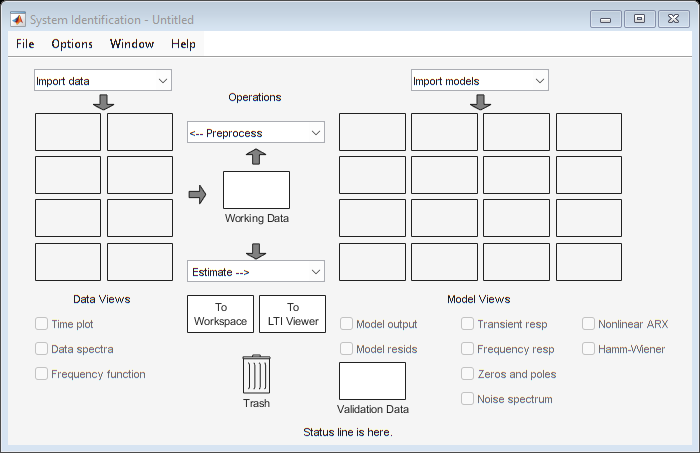

 systemIdentification % launches the systemIdentification utility

**Step 2: **Open the **Import data** dropdown menu and select **Time domain data...**. This launches the **Import Data** menu. Under the **Workspace Variable** section, fill in the **Input** and **Output** variable names, and set up the **Data Information** section as shown below. This sets the start time to 0 and sets the sampling time to that of the Simulink model used (2ms). 

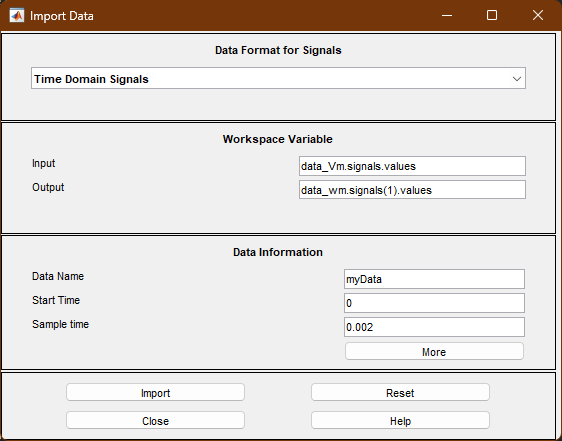

**Step 3: **Click on **Import** and then **Close** the **Import Data** menu. Check the Time plot option to view the data.

**Step 4: **Under the **Operations** section, open the **Preprocess** drop down menu and click on **Select Range...**. Set the options in the **Select Range** menu to those shown below (left image) and then click on Insert. Do not close the **Select Range** menu. Modify the options in the **Select Range** menu to those shown below and then click on **Insert** again. Close the **Select Range** menu.

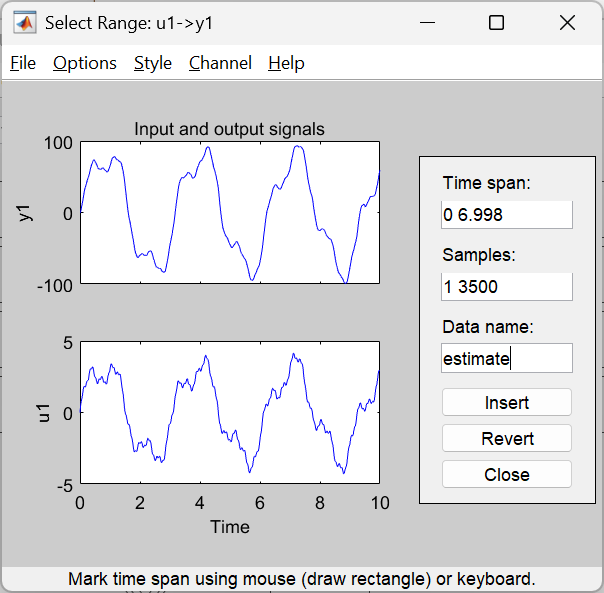  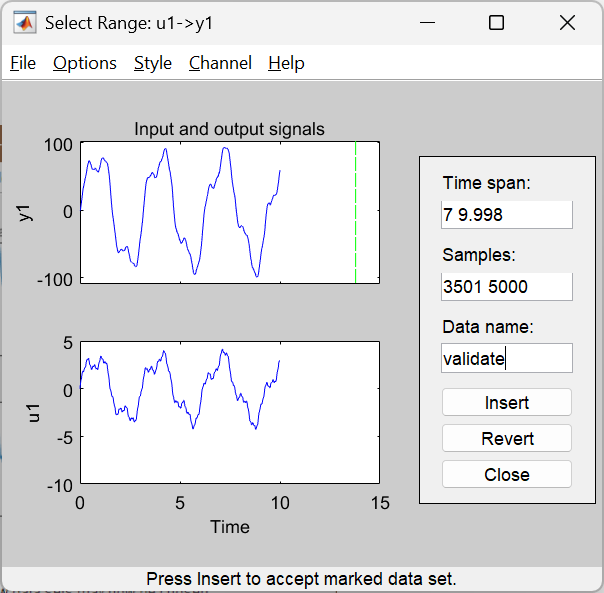

You should now have 2 additional data entries in the imported data, representing data for estimation as well as validation. The first 7 seconds of data will be used to estimate a model for the Qube Servo and last 3 seconds to validate the model. 

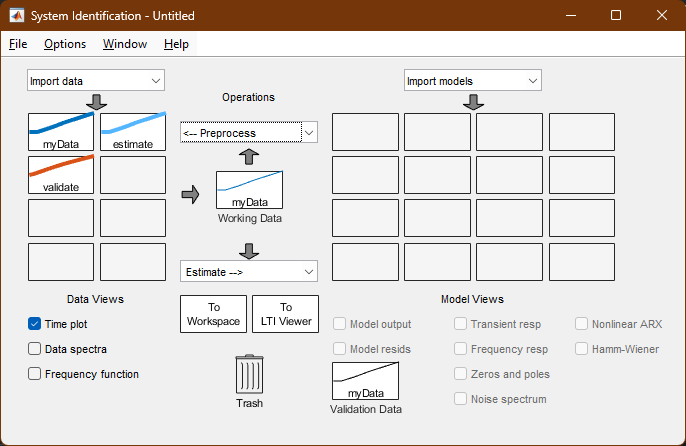

**Step 5: **Click and drag the **estimate** data to the **Working Data** section and the **validate** data to the **Validation Data** section. 

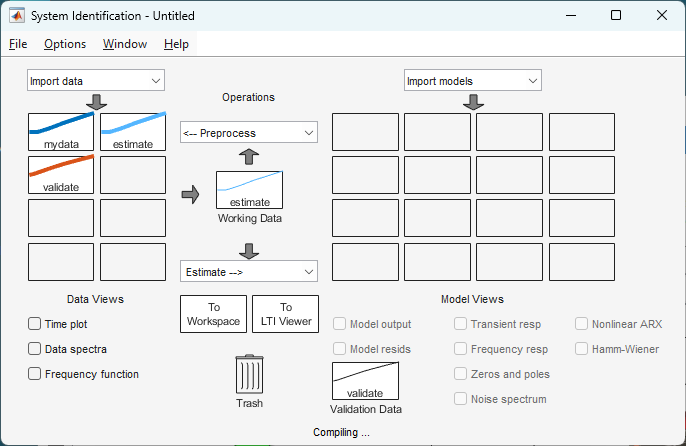

**Step 6: **Under the **Estimate **drop down menu, select **Transfer Function models** to open the **Estimate Transfer Functions** utility. 

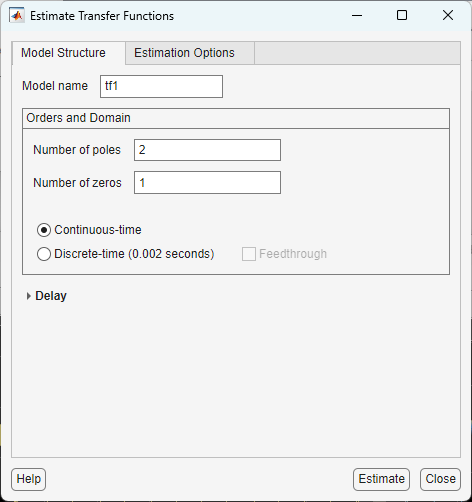

**Assessment 3**: Based on the results obtained from the [Step Response](matlab:open('./qube_servo_3_step_response_model.mlx')) lab, what should the number of poles and zeros be for a Transfer Function model representing the Qube Servo dynamics from voltage to speed?

**    Solution:** Based on the Step Response lab, a first order transfer function with 0 zeros and 1 pole can be used to model the Qube Servo, similar to, 

    
$$\frac{Y(s)}{U(s)} = \frac{K}{\tau s + 1}$$


**Step 6: **Set the number of poles and zeros according to your response from Assessment 3. Ensure that the **Domain** is set to **Continuous-time**, rename the model to **first_order1** and click on **Estimate**. 

**Step 7:** Analyze the **Identification Progress** results as well as the fit quality percentage indicator, similar to the result shown below. When done, click on **Close**. 

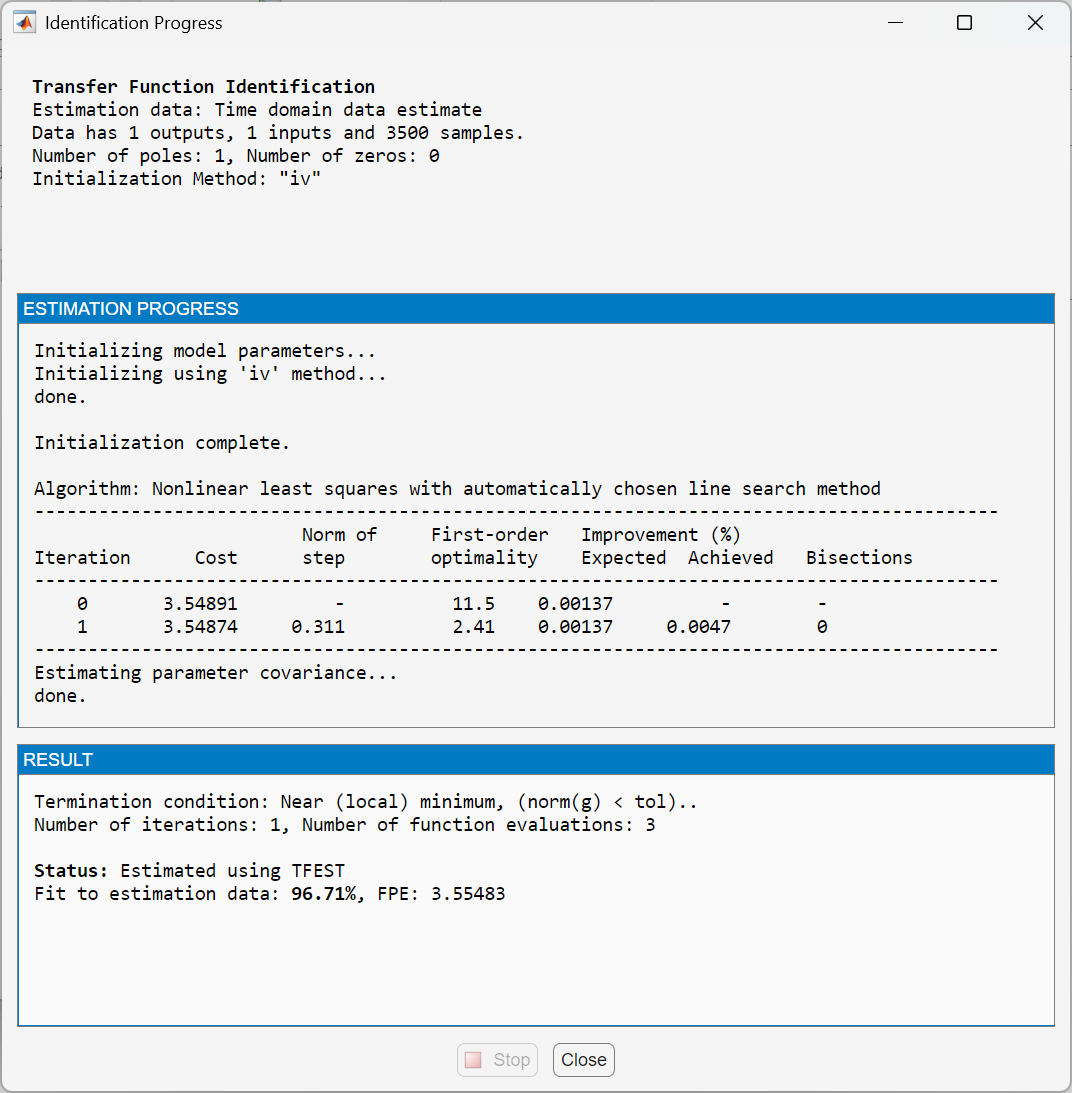

**Step 8**: Back in the **System Identification** menu, you will observe a new model on the right-half of the menu labeled **tf1**. Right-click the model, which should launch a menu expanding on the properties of this model. 

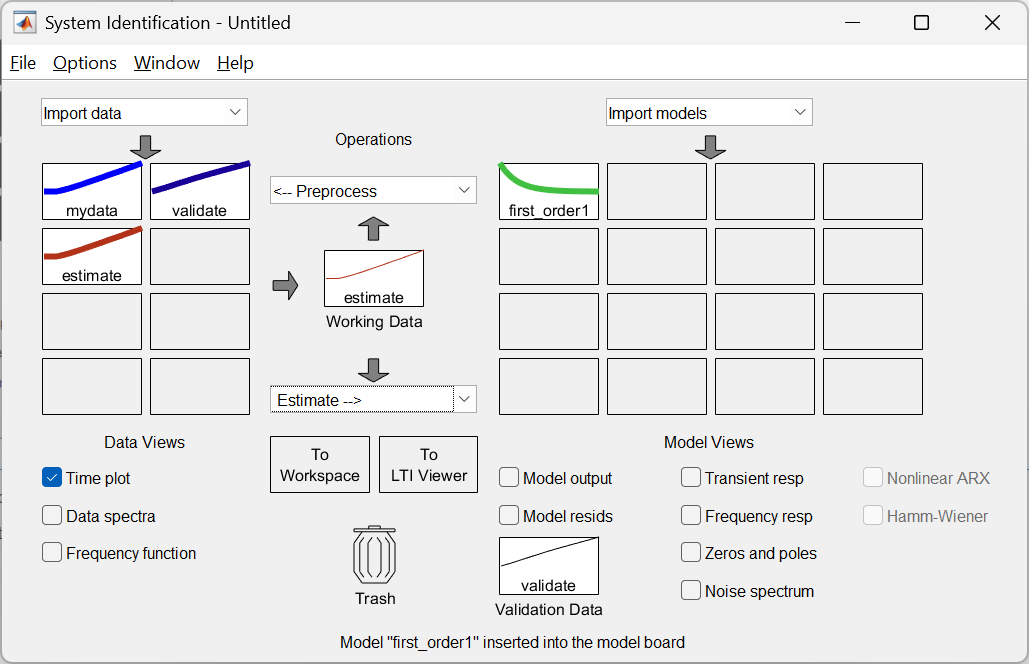

**Assessment 4**: What transfer function do you obtain from system identification? How does this compare to the one from the [Step Response](matlab:open('./qube_servo_3_step_response_model.mlx')) lab? 

**    Solution:** The transfer function obtained should be first order, but in a different format. The one obtained from System Identification is, 

    
$$\frac{\omega(s)}{V(s)} = \frac{294.4}{s + 11.36}$$


    By factoring out 11.03 from the numerator and denominator, we obtain, 

    
$$\frac{\omega(s)}{V(s)} = \frac{25.92}{0.088s + 1}$$


    The result from the Step Response lab has a similar time constant of 0.092s, but a smaller speed constant gain. 

    
$$\frac{\omega(s)}{V(s)} = \frac{26.6}{0.092s + 1}$$


**Step 9**: Back in the Simulink Model `q_qube3_system_identification.slx`, change the **Transfer Function** to match the one obtained from **System Identification**, and run the model again. You should see a result similar to one below.

 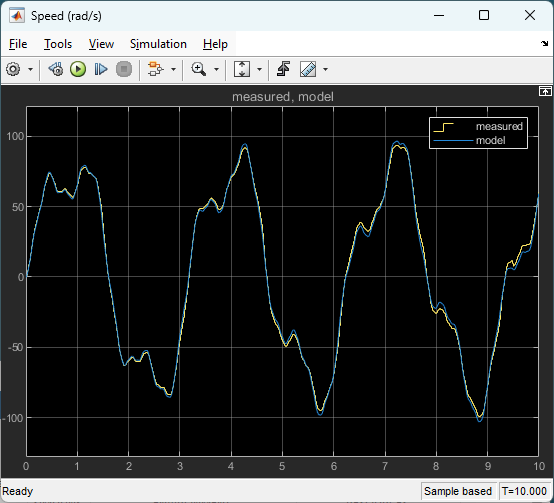

**Assessment 5**: Does the model match the data measured from the Qube Servo? Why does your transfer function differ from that obtained from the [Step Response](matlab:open('./qube_servo_3_step_response_model.mlx')) lab? 

**    Solution:** The modeled data matches the measurement quite accurately as seen from the Speed (rad/s) scope above. The transfer functions are quite similar in terms of the speed gain as well as time constant.

    The minor variances are accounted for by the different command input range/frequencies used in the step response lab (step wave) versus system identification (complex sinusoid). 

**Step 10**: Click on the *Exit to Main Menu *button in the top right corner of QLabs to exit the Qube-Servo 3 DC Motor Virtual Experiment workspace.

**Step 11**: Log off QLabs by clicking on the *Logout *button and click on *Exit* to shut down the application.